# **WM9QE: Applied Statistics for Artificial Intelligence**

## Template Discrete Distributions 

This MATLAB Live Script is a suppliment to the [name of the session] session. Full detail of the lectures and examples are availabe on the Moodle page here [add hyperlink]. 

## Section 1. Binomial Distribution

Descriptions, theories and equations. 

`MATLAB Help: `[`y`](https://uk.mathworks.com/help/releases/R2024b/stats/binopdf.html?searchHighlight=binopdf&s_tid=doc_srchtitle#mw_3f634fd4-dbd0-4afa-8c70-be4d5f2614fa) `=` `binopdf``(`[`x`](https://uk.mathworks.com/help/releases/R2024b/stats/binopdf.html?searchHighlight=binopdf&s_tid=doc_srchtitle#mw_bd43323e-13cc-4d69-b684-f3d11567c51a)`,`[`n`](https://uk.mathworks.com/help/releases/R2024b/stats/binopdf.html?searchHighlight=binopdf&s_tid=doc_srchtitle#mw_70ca4805-10eb-4959-bba9-f5de1e25a8b7)`,`[`p`](https://uk.mathworks.com/help/releases/R2024b/stats/binopdf.html?searchHighlight=binopdf&s_tid=doc_srchtitle#mw_41215d82-60d1-4f3b-9457-7e6e112b38d5)`)` computes the binomial probability density function at each of the values in `x` using the corresponding number of trials in `n` and probability of success for each trial in `p`.

`x`, `n`, and `p` can be vectors, matrices, or multidimensional arrays of the same size. Alternatively, one or more arguments can be scalars. The `binopdf` function expands scalar inputs to constant arrays with the same dimensions as the other inputs.

### **Example 1.1 Exhaust Pipes**

 A small manufacturing company that produces customized exhaust pipes for cars sells 20 products to its customers every week. Customers are a little bit concerned about quality and have raised a lot of complaints over the last couple of months. After conducting some experiments, the company found out that there is a 15% chance that a product can be defective. Are the customers right to complain?

clc; clear all;
% Parameters
n = 20;      % number of trials
p = 0.15;    % probability of success

% Initialize arrays
r = 0:n;                     % possible values of r
prob = binopdf(r, n, p);     % binomial probabilities
prob_float = round(prob, 5); % format to 5 decimal places
percentage = round(prob * 100, 5);

% Create a table
T = table(r', prob_float', percentage', ...
    'VariableNames', {'r', 'P(r)', 'P(r) %'});

% Display the table
T

T = 21×3 table
    r      P(r)      P(r) % 
    __    _______    _______

     0    0.03876      3.876
     1     0.1368      13.68
     2    0.22934     22.934
     3    0.24283     24.283
     4    0.18212     18.212
     5    0.10285     10.285
     6    0.04537     4.5373
     7    0.01601     1.6014
     8    0.00459    0.45922
     9    0.00108    0.10805
    10    0.00021    0.02097
    11      3e-05    0.00336
    12          0    0.00045
    13          0      5e-05
    14          0          0
    15          0          0


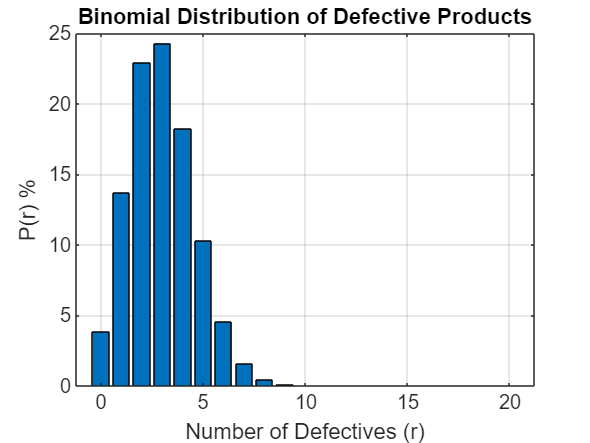

% Parameters
n = 20;      % number of trials
p = 0.15;    % probability of success

% Compute binomial probabilities
r = 0:n;
prob = binopdf(r, n, p);
percentage = prob * 100;

% Plot the bar chart
bar(r, percentage);

% Set the title and axis labels
title('Binomial Distribution of Defective Products');
xlabel('Number of Defectives (r)');
ylabel('P(r) %');

% Display grid for better readability (optional)
grid on;

**Decision:** Customers are right to complain

Apparently, an E(x) = 3 in 20 is not good performance and therefore customers are right to complain. A process improvement program to reduce the probability of having defective products is urgent.

## Section 2. Hypergeometric Distribution

Descriptions, theories and equations. 

Matlab Help: `Y =` `hygepdf``(X,M,K,N)` computes the hypergeometric pdf at each of the values in `X` using the corresponding size of the population, `M`, number of items with the desired characteristic in the population, `K`, and number of samples drawn, `N`. `X`, `M`, `K`, and `N` can be vectors, matrices, or multidimensional arrays that all have the same size. A scalar input is expanded to a constant array with the same dimensions as the other inputs.

The parameters in `M`, `K`, and `N` must all be positive integers, with `N` ≤ `M`. The values in `X` must be less than or equal to all the parameter values.

The hypergeometric pdf is

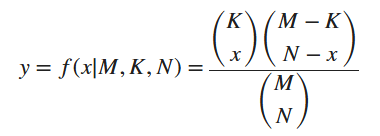

The result, *y*, is the probability of drawing exactly *x* of a possible *K* items in *n* drawings without replacement from a group of *M* objects.

### **Example 2.1 Testing Chipsets**

A company that produces chipsets in batches of 20 and they would like to test their performance. Testing such components can be very expensive so they decided to test a sample of 5 products from a batch. Testing occurs without replacement of defective products. From past data, it is known that the defect rate is around 10%. Could you model the distribution of the defective products in the sample chosen?

% Parameters
M = 20;           % Total number of chipsets in a batch
n = 5;            % Number of chipsets tested
N = floor(M * 0.10);  % Number of defective chipsets in the batch (10% of 20)

% Initialize arrays
r_values = 0:n;
probabilities = hygepdf(r_values, M, N, n);
percentages = probabilities * 100;

% Create a table
distributionTable = table(r_values', probabilities', percentages', ...
    'VariableNames', {'r', 'P(r)', 'P(r) %'});

% Display the table
distributionTable

distributionTable = 6×3 table
    r      P(r)      P(r) %
    _    ________    ______

    0     0.55263    55.263
    1     0.39474    39.474
    2    0.052632    5.2632
    3           0         0
    4           0         0
    5           0         0


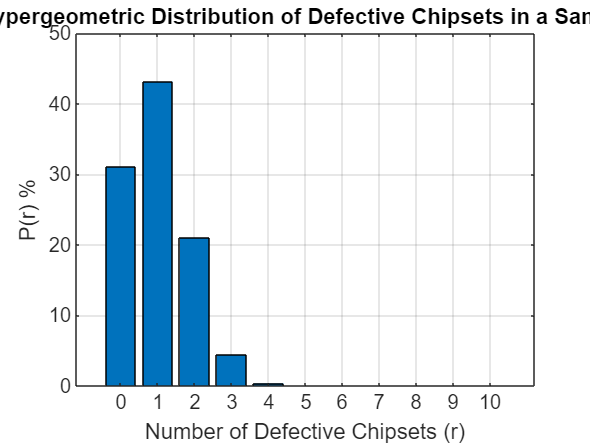


% Sample 'r' values and corresponding probabilities (as percentages)
% These should come from the hypergeometric distribution calculation
% Example placeholders:
r = 0:10;  % Replace with actual r values
percentage = hygepdf(r, 50, 5, 10) * 100;  % Replace parameters with real ones

% Plotting the histogram (bar chart)
bar(r, percentage);

% Set the labels
title('Hypergeometric Distribution of Defective Chipsets in a Sample');
xlabel('Number of Defective Chipsets (r)');
ylabel('P(r) %');

% Optional: add grid for clarity
grid on;

**Decision:** Use of the hypergeometric destribution

The E(x) = 0.5 in a sample of 5 products, which is a logical value provided that x = 0 and x = 1 have the highest chances of being the case. If the inspection process starts producing more defective process, for example constantly 3 or 4 chipsets, then the process needs to be investigated.

## Section 3. Negative Binomial Distribution

Descriptions, theories and equations. 

### **Example 3.1 Customer Inspection**

A customer is interested in observing the production process of a company the produces red tiles. While the process is very capable, there is a probability of 0.5% that the tile produced will not be of the right colour. While this is not a huge cost for the company, it may look bad if a defective tile is produced during the inspection. The customer wants to inspect 20 tiles that have been produced consecutively. What is the probability of the customer inspecting a tile that is defective?

% Parameters
n_tiles = 20;             % Number of tiles to inspect
p_defective = 0.005;      % Probability of a tile being defective

% Initialize arrays
x_values = (1:n_tiles)';
p_x = p_defective .* (1 - p_defective).^(x_values - 1);     % Geometric PMF
p_cumulative = 1 - (1 - p_defective).^x_values;             % Cumulative probability
p_x_percent = p_x * 100;
p_cumulative_percent = p_cumulative * 100;

% Create a table
probabilitiesTable = table(x_values, ...
                           round(p_x, 4), ...
                           round(p_x_percent, 4), ...
                           round(p_cumulative_percent, 3), ...
                           'VariableNames', {'x', 'P(x)', 'P(x) %', 'Cum_Pr %'});

% Display the table
probabilitiesTable

probabilitiesTable = 20×4 table
    x      P(x)     P(x) %    Cum_Pr %
    __    ______    ______    ________

     1     0.005       0.5       0.5  
     2     0.005    0.4975     0.997  
     3     0.005     0.495     1.493  
     4    0.0049    0.4925     1.985  
     5    0.0049    0.4901     2.475  
     6    0.0049    0.4876     2.963  
     7    0.0049    0.4852     3.448  
     8    0.0048    0.4828     3.931  
     9    0.0048    0.4803     4.411  
    10    0.0048    0.4779     4.889  
    11    0.0048    0.4756     5.365  
    12    0.0047    0.4732     5.838  
    13    0.0047    0.4708     6.309  
    14    0.0047    0.4685     6.777  
    15    0.0047    0.4661     7.243  
    16    0.0046    0.4638     7.707  


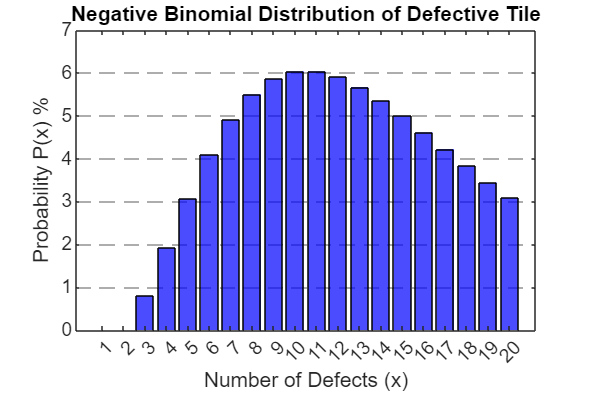


% Example values (replace these with your actual data)
x = 1:n_tiles;  % x-axis: number of defects
r_param = 3;    % number of successes (this is the 'r' in the negative binomial distribution)
p_param = 0.2;  % probability of success
percentage = nbinpdf(x - r_param, r_param, p_param) * 100;  % P(x) %; shifted by r if needed

% Plot the histogram (bar chart)
bar(x, percentage, 'FaceColor', [0 0 1], 'FaceAlpha', 0.7);  % blue bars with 70% opacity

% Set the plot title and axis labels
title('Negative Binomial Distribution of Defective Tile');
xlabel('Number of Defects (x)');
ylabel('Probability P(x) %');

% Set x-axis ticks
xticks(1:n_tiles);

% Add dashed grid lines along y-axis
grid on;
ax = gca;
ax.YGrid = 'on';
ax.XGrid = 'off';
ax.GridLineStyle = '--';
ax.GridAlpha = 0.5;  % transparency


% Adjust layout
set(gcf, 'Position', [100, 100, 600, 400]);  % optional: size the figure window

**Decision:** Bad idea

The probability is equal to 9.54% which is not as low as expected and the company will probably take a risk of having the customer inspecting the production process.

## Section 4. Poisson Distribution

Descriptions, theories and equations. 

### **Example 4.1 M**anufacturing Company

A quality inspector of a manufacturing company is responsible for tracing bumps on a specific product’s surface. In case there are any bumps the product needs to be further processed and repaired before it is sent to the customer. The customer offered that if the company can guarantee that the delivered products will have less than 4 bumps/per product, then they can make the extra processing in their facilities at no extra cost, as they will benefit from earlier delivery. However, if this deal is accepted, then there will be a free replacement penalty for products with 5 bumps or more. Should the company accept the offer?

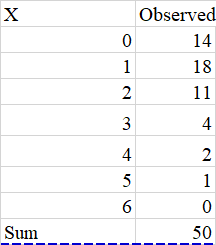


% Observed data (number of occurrences => frequency)
observed_data = containers.Map({0, 1, 2, 3, 4, 5, 6}, [14, 18, 11, 4, 2, 1, 0]);

% Total observations
values = cell2mat(values(observed_data));

Unable to use a value of type containers.Map as an index.

total_observations = sum(values);

% Calculate mean lambda (λ)
sum_vc = 0;
keys_obs = cell2mat(keys(observed_data));
for i = 1:length(keys_obs)
    value = keys_obs(i);
    count = observed_data(value);
    sum_vc = sum_vc + value * count;
end
mean_lambda = sum_vc / total_observations;

% Compute P(x) and Expected values
max_x = max(keys_obs);
X_vals = 0:max_x;
observed = zeros(size(X_vals));
P_x = zeros(size(X_vals));
expected = zeros(size(X_vals));

for i = 1:length(X_vals)
    x = X_vals(i);
    if isKey(observed_data, x)
        observed(i) = observed_data(x);
    end
    P_x(i) = poisspdf(x, mean_lambda);
    expected(i) = P_x(i) * total_observations;
end

% Add summary row
total_P = sum(poisspdf(keys_obs, mean_lambda));
P_x_percent = P_x * 100;

% Create and display the results table
T = table([X_vals, NaN]', [observed, total_observations]', ...
          [P_x_percent, total_P * 100]', [expected, total_observations]', ...
          'VariableNames', {'X', 'Observed', 'P(x) %', 'Expected'});

T

% Assume these vectors come from your previous table (excluding the sum row)
% Example:
X_vals = 0:max_x; % x values (number of bumps)
observed = observed(1:end);  % observed counts vector (exclude sum)
expected = expected(1:end);  % expected counts vector (exclude sum)

% Bar width and positions for grouped bars
bar_width = 0.35;
n = length(X_vals);
index = 1:n;

% Create grouped bar plot
figure;
hold on;
b1 = bar(index, observed, bar_width, 'FaceColor', 'b', 'FaceAlpha', 0.6);
b2 = bar(index + bar_width, expected, bar_width, 'FaceColor', 'r', 'FaceAlpha', 0.6);
hold off;

% Set x-axis labels in the middle of the grouped bars
xticks(index + bar_width/2);
xticklabels(string(X_vals));

% Labels and title
xlabel('Number of Bumps (X)');
ylabel('Counts');
title('Observed vs Expected');

% Add legend
legend('Observed', 'Expected');

% Adjust layout (optional)
set(gca, 'Box', 'off');

**Decision:** Low probability

The data seems to follow the Poisson distribution and therefore it can be said that the probability of having more than 4 bumps in a product is low.

## Section 5. Discrete Distributions Exercises

Please complete the exercises below as part of your independent study.

### Exercise 5.1: Local Bakery 

A local bakery that specializes in artisanal bread sells 50 loaves every day. Recently, there has been an increase in customer complaints regarding the quality of the bread. After thorough analysis, the bakery found that there is a 10% chance that a loaf may be underbaked. Should customers be concerned about the bread quality?

%Use this place to write and run your code

### Exercise 5.2: E-commerce Fulfillment Center

In an e-commerce fulfillment center, a team is responsible for packaging electronic gadgets. The team has observed that, on average, there are 2.5 packaging errors (such as incorrect labels or missing components) per batch of 20 products. The e-commerce platform has offered a deal: if the company can ensure fewer than 4 errors per batch, the platform will cover the cost of expedited shipping for all orders in that batch. However, if the error count reaches 5 or more, the company will have to provide free replacements for the affected products. Should the e-commerce company accept this offer?

a) What is the probability of exactly three errors?

b) What is the probability of less than three errors?

%Use this place to write and run your code